# Motor

% Created by: Giacomo Mastroddi, September 2023
clear; close all;

par = get_car_param();

## Data from Image

Motor data obtained using [https://apps.automeris.io/wpd/](https://apps.automeris.io/wpd/) on this image

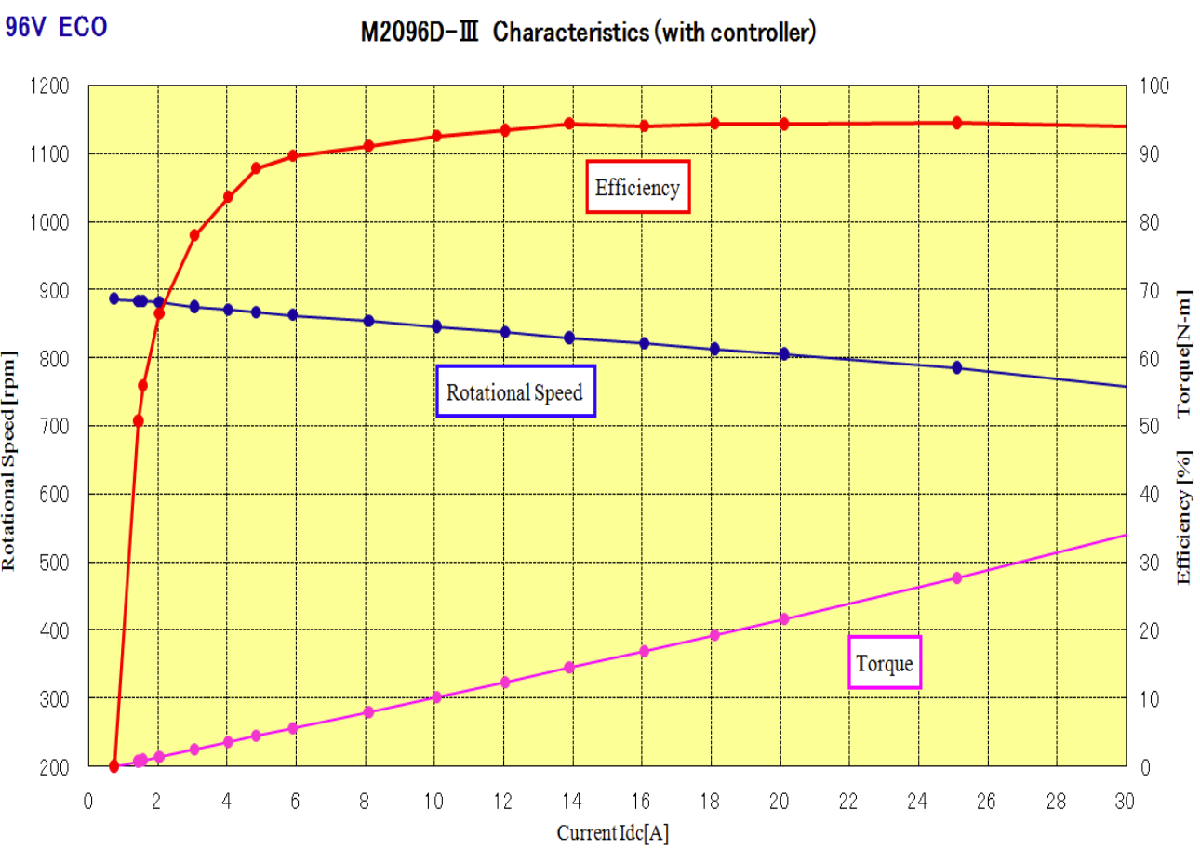

rotationalSpeed = readmatrix("rotationalSpeed.csv");
rotationalSpeedXcurrent = rotationalSpeed(:,1);
rotationalSpeedY = rotationalSpeed(:,2);

torque = readmatrix("torque.csv");
torqueXcurrent = torque(:,1);
torqueY = torque(:,2);

efficiency = readmatrix("efficiency.csv");
efficiencyXcurrent = efficiency(:,1);
efficiencyY = efficiency(:,2);

Curve fitting using cftool

% f(x) with x = current
rotationalSpeedFit = @(x) -4.925*x + 825.3; %rpm
torqueFit = @(x) 1.159*x - 1.44;
efficiencyFit = @(x) -75.45./(x-0.073) - 0.235*x + 103.07;

Plots

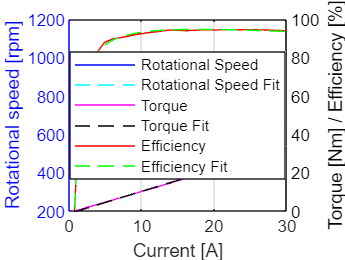

figure

% Left y-axis for rotational speed
yyaxis left
hold on
plot(rotationalSpeedXcurrent, rotationalSpeedY, 'b-', 'DisplayName', 'Rotational Speed')
plot(rotationalSpeedXcurrent, rotationalSpeedFit(rotationalSpeedXcurrent), 'c--', 'DisplayName', 'Rotational Speed Fit')
ylabel("Rotational speed [rpm]")
ylim([200 1200])
set(gca, 'YColor', 'b')

% Right y-axis for torque and efficiency
yyaxis right
hold on
plot(torqueXcurrent, torqueY, 'm-', 'DisplayName', 'Torque')
plot(torqueXcurrent, torqueFit(torqueXcurrent), 'k--', 'DisplayName', 'Torque Fit')
plot(efficiencyXcurrent, efficiencyY, 'r-', 'DisplayName', 'Efficiency')
plot(efficiencyXcurrent, efficiencyFit(efficiencyXcurrent), 'g--', 'DisplayName', 'Efficiency Fit')
ylabel("Torque [Nm] / Efficiency [%]")
ylim([0 100])
set(gca, 'YColor', 'k')

xlabel("Current [A]")
grid on; box on;
legend('Location', 'best')

## Power Analysis

Relevant values for power

voltage = 96; %V
maxCurrent = par.P_el_max / voltage; %A
current = linspace(1, maxCurrent, floor(maxCurrent)); %A
elPower = voltage * current; %W

mechPower = torqueFit(current) .* rotationalSpeedFit(current)*2*pi/60; %W

Plot

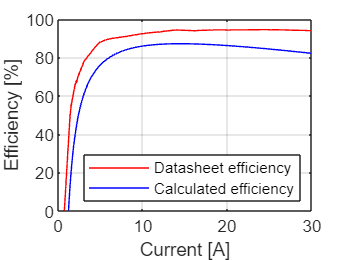

figure
plot(efficiencyXcurrent, efficiencyY,'r','DisplayName','Datasheet efficiency')
hold on
eff = (torqueFit(efficiencyXcurrent) .* rotationalSpeedFit(efficiencyXcurrent)*2*pi/60) ./ (efficiencyXcurrent .* voltage);
plot(efficiency(:,1), eff*100,'b','DisplayName','Calculated efficiency')
legend('Location','southeast')
xlabel("Current [A]")
ylabel("Efficiency [%]")
xlim([0 30])
ylim([0 100])
grid on
box on

Estimation of P0

P0 = round(interp1(mechPower, elPower, 0));
fprintf('Datasheet estimation: \n P0 = %d W', P0)

Datasheet estimation: 
 P0 = 119 W

#### Curve fitting using linear least squares

A = elPower';
b = mechPower';
lsqrResult = lsqr(A, b);

lsqr converged at iteration 1 to a solution with relative residual 0.064.


fprintf('Efficiency estimation with LSQR: \n e = %.3f', lsqrResult)

Efficiency estimation with LSQR: 
 e = 0.769

leastSquareCurve = @(x) lsqrResult(1) * x - P0 * lsqrResult(1);

mechPowerWillanModel = @(x) par.e_mot * x - par.P_0;

Plot

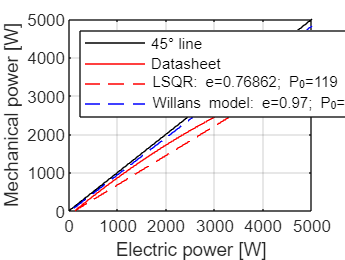

figure
plot([0 par.P_el_max], [0 par.P_el_max],'k','DisplayName','45° line')
hold on
plot(elPower, mechPower,'r','DisplayName','Datasheet')
plot(elPower, leastSquareCurve(elPower),'--r','DisplayName',['LSQR: e=',char(num2str(lsqrResult)),'; P_0=',char(num2str(P0)), ' W'])
plot(elPower, mechPowerWillanModel(elPower),'--b','DisplayName',['Willans model: e=',char(num2str(par.e_mot)),'; P_0=',char(num2str(par.P_0)), ' W'])
legend('Location','northwest')
xlabel("Electric power [W]")
ylabel("Mechanical power [W]")
xlim([0 par.P_el_max])
ylim([0 par.P_el_max])
grid on
box on